Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# TE-mode in circular waveguide (Section 6.2)

Volker Ziemann, 211111, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

This is practically the same example as TEwaveguide.mlx with the rectangylar waveguide. I will therefore be brief with the explanations. First we define the geometry as a circle

clear all; close all; 
waveguide=[1;0;0;0.1];    % circle
gd=[waveguide];           % assemble geometry
ns=char('waveguide')';    % names of the regions                 
sf='waveguide'; 
g=decsg(gd,sf,ns);

and create the model, inspect the names of edges and faces, before assigning boundary conditions, specify the material, and mesh the geometry; the same steps as for the rectangular waveguide.

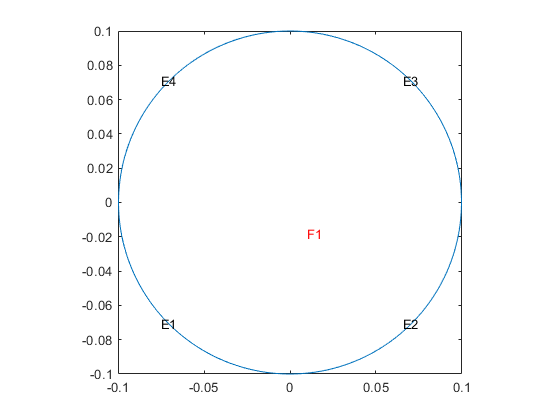

model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis equal

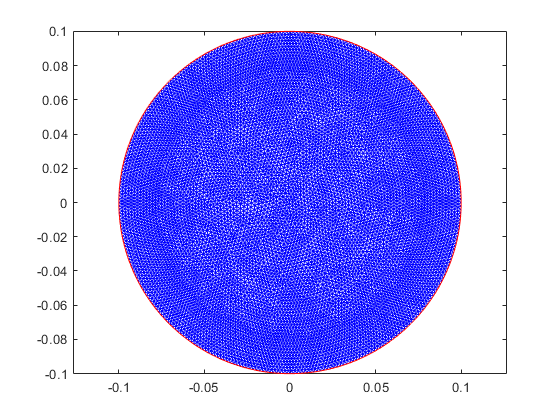

applyBoundaryCondition(model,'Edge',[1:4],'q',0,'g',0); % von Neumann
specifyCoefficients(model,'m',0,'d',1,'c',1,'a',0,'f',0,'Face',1);
generateMesh(model,'Hmax',0.002); 
figure; pdemesh(model); axis equal;

Now we use `solvepdeeig()` to return a structure `result,` which contains `eigenvalues` and eigenvectors `Hz` of Equation 6.2, evaluated in the range specified as the second argument to  `solvepdeeig().`

result=solvepdeeig(model,[1,2000]); 

              Basis= 10,  Time=   0.85,  New conv eig=  0
              Basis= 11,  Time=   0.89,  New conv eig=  0
              Basis= 12,  Time=   0.91,  New conv eig=  0
              Basis= 13,  Time=   0.93,  New conv eig=  0
              Basis= 14,  Time=   0.95,  New conv eig=  0
              Basis= 15,  Time=   0.97,  New conv eig=  0
              Basis= 16,  Time=   0.98,  New conv eig=  0
              Basis= 17,  Time=   1.00,  New conv eig=  0
              Basis= 18,  Time=   1.01,  New conv eig=  3
              Basis= 19,  Time=   1.03,  New conv eig=  3
              Basis= 20,  Time=   1.05,  New conv eig=  3
              Basis= 21,  Time=   1.07,  New conv eig=  3
              Basis= 22,  Time=   1.10,  New conv eig=  3
              Basis= 23,  Time=   1.15,  New conv eig=  3
              Basis= 24,  Time=   1.17,  New conv eig=  3
              Basis= 25,  Time=   1.18,  New conv eig=  3
              Basis= 26,  Time=   1.20,  New conv eig=  3
              

eigenvalues=result.Eigenvalues; 
Hz=result.Eigenvectors;

The function `meshToPet()` returns information about the points `p`, the edges `e`, and triangles` t`, which we need to calculate the gradients that give us the fields from Equation 6.1. Then we select the mode and plot its eigenvector Hz with `pdesurf().`

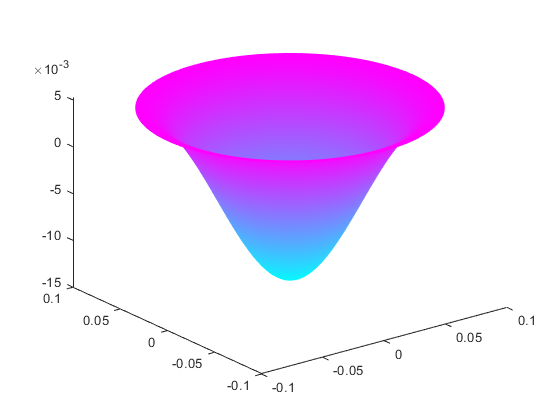

[p,e,t]=meshToPet(model.Mesh);
mode=5;
[dHx,dHy]=pdegrad(p,t,Hz(:,mode)); Hx=-dHx; Hy=-dHy; Ex=dHy; Ey=-dHx;
figure; pdesurf(p,t,Hz(:,mode)); 

Finally we plot the electric and magnetic fields of the selected `mode` as arrows.

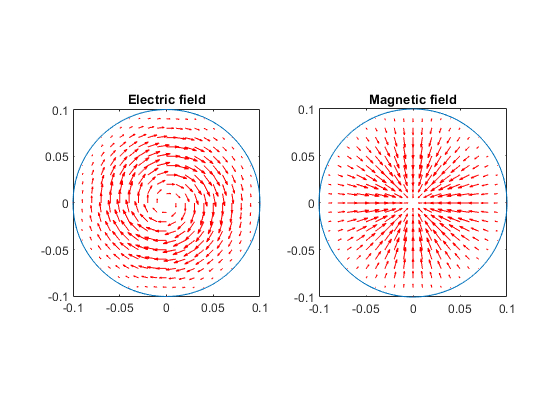

figure;
subplot(1,2,1); pdegplot(model); hold on; pdeplot(model,'flowdata',[Ex;Ey]); 
axis square; title('Electric field');
subplot(1,2,2); pdegplot(model); hold on; pdeplot(model,'flowdata',[Hx;Hy]); 
axis square; title('Magnetic field');

Now inspect the different modes and increase the range of eigenvalues!